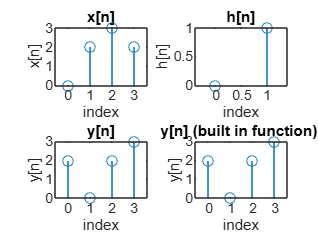

x=input("Enter x[n]:");
h=input("enter h[n]:");
N=max(length(x), length(h));
X=[x,zeros(1,N-length(x))];
H=[h,zeros(1,N-length(h))];
tr_y=transpose(zeros(1,N));
mat=zeros(N,N);
trx=transpose(X);
trh=transpose(H);
for i=0:N-1
    mat(:,i+1)=circshift(trx,i);
end
tr_y=mat*trh;
y=transpose(tr_y);
subplot(221)
stem(0:length(x)-1,x);
xlabel("index");
ylabel("x[n]");
title("x[n]");
subplot(222)
stem(0:length(h)-1,h);
xlabel("index");
ylabel("h[n]");
title("h[n]");
subplot(223)
stem(0:length(y)-1,y);
xlabel("index");
ylabel("y[n]");
title("y[n]");
subplot(224)
stem(0:length(y)-1,cconv(x,h,N));
xlabel("index");
ylabel("y[n]");
title("y[n] (built in function) "); 